# Using the Leaderboard Toolbox

Edit this file directly to add a new player, or by using the addPlayerToFile function.

type players.csv

Name,ID
Michael Cappello,34524
Andrew Newell,631608
Grzegorz Knor,1861624
Evan,3303717
Yaroslav,3354683
PurpleDiab,5960633
cokakola,7164325
Jakub Mrowka,8171411
Erik Luiten,8960155
Jiahang Li,11433059


player_file = which("players.csv");
players = readtable(player_file,"TextType","string")

players = 10×2 table
           Name               ID    
    __________________    __________

    "Michael Cappello"         34524
    "Andrew Newell"       6.3161e+05
    "Grzegorz Knor"       1.8616e+06
    "Evan"                3.3037e+06
    "Yaroslav"            3.3547e+06
    "PurpleDiab"          5.9606e+06
    "cokakola"            7.1643e+06
    "Jakub Mrowka"        8.1714e+06
    "Erik Luiten"         8.9602e+06
    "Jiahang Li"          1.1433e+07


## Make the HTML Leaderboard File

f = 'leaderboard.html';
makeLeaderboard(f,players.ID)

## Collect the Data

Run this at a regular interval to get the latest scores.

f = 'scores.csv';
scoreTable = gatherScoreData(f,players.ID)

scoreTable = 28×3 timetable
            Time                Id        Score    Badges
    ____________________    __________    _____    ______

    27-Mar-2019 12:54:26         34524    8340       10  
    27-Mar-2019 12:54:26    6.3161e+05    8720       22  
    27-Mar-2019 12:54:26    1.8616e+06    9090       15  
    27-Mar-2019 12:54:26    3.3037e+06    8750        9  
    27-Mar-2019 12:54:26    3.3547e+06    8425       15  
    27-Mar-2019 12:54:26    5.9606e+06    9000       10  
    27-Mar-2019 12:54:26    7.1643e+06    9780       39  
    27-Mar-2019 12:54:26    8.1714e+06    9545       12  
    27-Mar-2019 12:54:26    8.9602e+06    8755       10  
    27-Mar-2019 12:54:26   

## Make a Leaderboard Table

t1 = datetime('now')

t1 = datetime
   28-Apr-2020 11:47:19


currentTable = leaderTableAtTime(players, scoreTable, t1)

currentTable = 10×4 table
           Name               Id        Score    Badges
    __________________    __________    _____    ______

    "Evan"                3.3037e+06    12230      24  
    "cokakola"            7.1643e+06    11450      50  
    "Jiahang Li"          1.1433e+07    10980      22  
    "Andrew Newell"       6.3161e+05     9700      30  
    "Jakub Mrowka"        8.1714e+06     9475      11  
    "PurpleDiab"          5.9606e+06     9110      10  
    "Grzegorz Knor"       1.8616e+06     9090      15  
    "Erik Luiten"         8.9602e+06     8755      10  
    "Michael Cappello"         34524     8610      11  
    "Yaroslav"            3.3547e+06     8375      14  


## Plot Player Scores Over Time

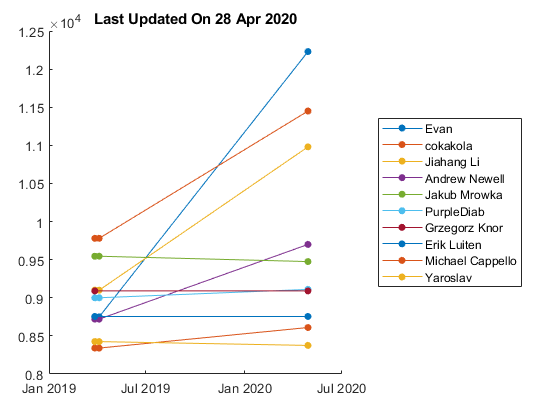

id = currentTable.Id;
clf
hold all
for i = 1:length(id)
    ix = find(scoreTable.Id == id(i));
    plot(scoreTable.Time(ix),scoreTable.Score(ix),'.-', ...
        'MarkerSize',18)
end
hold off
d =  max(scoreTable.Time);
d.Format = "dd MMM uuuu";
title(sprintf('Last Updated On %s',d))
legend(currentTable.Name,'Location',"eastoutside")

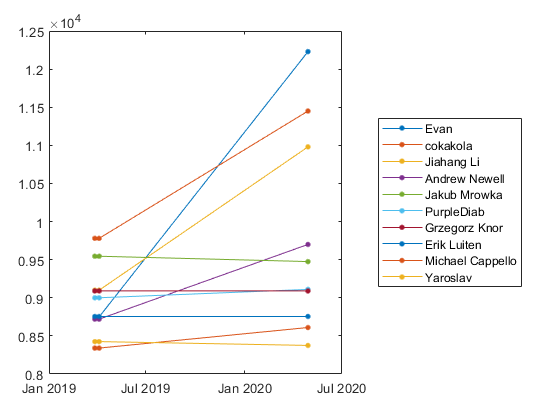

[scoreMatrix,t,playerNames] = makeScoreMatrix(scoreTable, players);

plot(t,scoreMatrix,'.-','MarkerSize',12)
legend(playerNames,"Location","eastoutside")

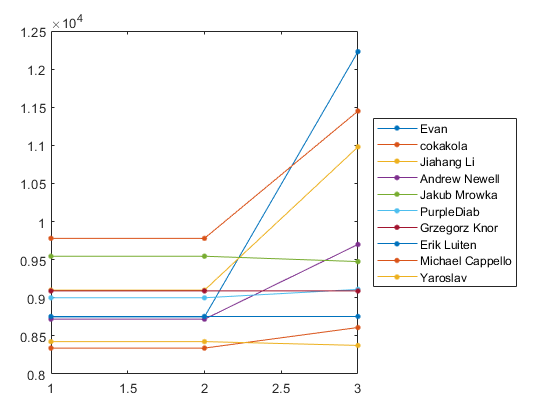

plot(scoreMatrix,'.-','MarkerSize',12)
legend(playerNames,"Location","eastoutside")

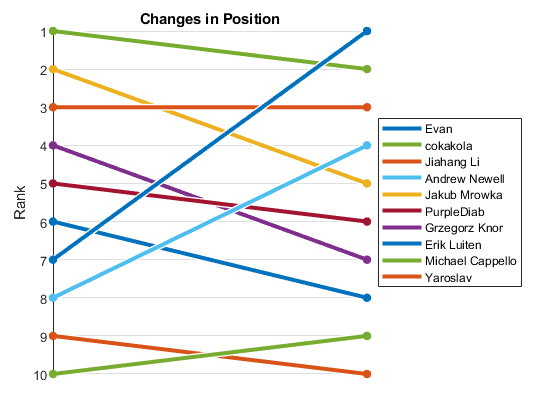

makeRankPlot(scoreMatrix, t, playerNames);

## Changes in the last 30 Days

t2 = datetime;
nDays = 30;
t1 = t2 - days(nDays)

t1 = datetime
   29-Mar-2020 11:47:27


dMinus30Table = leaderTableAtTime(players,scoreTable,t1);
currentTable = leaderTableAtTime(players,scoreTable,t2);

Rank = zeros(height(players),1);
RankChange = zeros(size(Rank));
ScoreChange = zeros(size(Rank));

for i = 1:height(currentTable)
    Rank(i) = i;
    ixOld = find(dMinus30Table.Id==currentTable.Id(i));
    if isempty(ixOld)
        RankChange(i) = NaN;
        ScoreChange(i) = currentTable.Score(i);
    else
        RankChange(i) = ixOld - Rank(i);
        ScoreChange(i) = currentTable.Score(i) - dMinus30Table.Score(ixOld);
    end
end

currentTable = [currentTable table(Rank,RankChange,ScoreChange)]

currentTable = 10×7 table
           Name               Id        Score    Badges    Rank    RankChange    ScoreChange
    __________________    __________    _____    ______    ____    __________    ___________

    "Evan"                3.3037e+06    12230      24        1          6           3480    
    "cokakola"            7.1643e+06    11450      50        2         -1           1670    
    "Jiahang Li"          1.1433e+07    10980      22        3          0           1880    
    "Andrew Newell"       6.3161e+05     9700      30        4          4            980    
    "Jakub Mrowka"        8.1714e+06     9475      11        5         -3            -70    
    "PurpleDiab"          5.9606e+06     9110      10        6         -1           

fprintf('Changes in the Last %d Days\n\n',nDays);

Changes in the Last 30 Days




for i = 1:height(currentTable)
    if isnan(currentTable.RankChange(i))
        rankStr = "New player this period";
    elseif currentTable.RankChange(i)<0
        rankStr = sprintf("Rank decreased by %d",abs(currentTable.RankChange(i)));
    elseif currentTable.RankChange(i)==0
        rankStr = "Rank unchanged"
    else
        rankStr = sprintf("Rank improved by %d",currentTable.RankChange(i));
    end
    fprintf("%2d. %20s: %4d (%s)\n", ...
        i,currentTable.Name(i), currentTable.Score(i), rankStr);
end

 1.                 Evan: 12230 (Rank improved by 6)
 2.             cokakola: 11450 (Rank decreased by 1)


rankStr = "Rank unchanged"

 3.           Jiahang Li: 10980 (Rank unchanged)
 4.        Andrew Newell: 9700 (Rank improved by 4)
 5.         Jakub Mrowka: 9475 (Rank decreased by 3)
 6.           PurpleDiab: 9110 (Rank decreased by 1)
 7.        Grzegorz Knor: 9090 (Rank decreased by 3)
 8.          Erik Luiten: 8755 (Rank decreased by 2)
 9.     Michael Cappello: 8610 (Rank improved by 1)
10.             Yaroslav: 8375 (Rank decreased by 1)
